clear;clc;clf;
% Data from 5/30/2023 - Forresti
format short g ; format compact 
folder_path = "/Users/nbonnie/MATLAB/stereo-calibration-free-firefly";
addpath(genpath(folder_path))
addpath(genpath(strcat(folder_path,"/data")))
fnames = dir(strcat(folder_path,"/data/*.mat"))

data1 = load(strcat(folder_path, "/data/", fnames(1).name));
data2 = load(strcat(folder_path, "/data/", fnames(2).name));
fns1 = fieldnames(data1);
fns2 = fieldnames(data2);

df1 = data1.(fns1{1}).xyt;
df2 = data2.(fns2{1}).xyt;
c1n = data1.(fns1{1}).n;
c2n = data2.(fns2{1}).n;

frame_width = data1.(fns1{1}).mov.Width;
frame_height = data1.(fns1{1}).mov.Height;

% Clean out noise and persistent objects:
df1 = removePersistentObjects(df1);
df2 = removePersistentObjects(df2);

c1_start = 3384;
c2_start = 2862;
dk = c2_start - c1_start;
% dkRobust.m not working for stereo
% [dk, dkRes] = dkRobust(c1n, c2n)

% Find all 1-flash-frames to calibrate on:
calTraj = extractCalibrationTrajectories(df1,df2,dk);

% Code in git will not run as is- extractCalTraj has been updated, but not
% in the main file "reconstruct360.m"
% [calTraj1,calTraj2] = extractCalibrationTrajectories(df1,df2,dk);

% Pin all points from C1 at 0,0 - plot all C2 displatement relative to C1
displacements = zeros(size(calTraj.j1, 1),2);
for i = 1:size(displacements,1)
    % X2 - X1, Y2 - Y1
    displacements(i,:) = [calTraj.j2(i,2)-calTraj.j1(i,2), calTraj.j2(i,1)-calTraj.j1(i,1)];
end

% Construct pdf for X & Y vars, plot

% Estimate a continuous pdf from the discrete data
[pdfx, xi]= ksdensity(displacements(:,1));
[pdfy, yi]= ksdensity(displacements(:,2));
% Create 2-d grid of coordinates and function values, suitable for 3-d plotting
[xxi,yyi]     = meshgrid(xi,yi);
[pdfxx,pdfyy] = meshgrid(pdfx,pdfy);
% Calculate combined pdf, under assumption of independence
pdfxy = pdfxx.*pdfyy; 
% Plot the results
mesh(xxi,yyi,pdfxy)
set(gca,'XLim',[min(xi) max(xi)])
set(gca,'YLim',[min(yi) max(yi)])

% TODO: Create saved data folder in dir
%
%
fnames = dir(strcat(pwd,"/*.mat"));
% Check to see if object already exists
% if ~ismember(strcat(fns1{1},"--",fns2{1},".mat"),{fnames.name})
if ~ismember(strcat(fns1{1},"--",fns2{1},".mat"),{fnames.name})
    disp('Estimating fundamental matrix; this may take a while (up to ~1hr)...')
    disp(datetime('now'))
    stereoParams = estimate360CameraParameters(calTraj.j1, calTraj.j2,'minSearch');
    disp('calibration complete.')
    disp(datetime('now'))
    save(strcat(fns1{1},"--",fns2{1}), 'stereoParams');
else
    %stereoParams = importdata("stereoParams.mat")
    stereoParams = importdata(strcat(fns1{1},"--",fns2{1},".mat"))
    disp(strcat('Fundamental matrix already exists for these files, loading:',strcat(fns1{1},"--",fns2{1},".mat")))
    
end

Estimating fundamental matrix; this may take a while (up to ~1hr)...


   25-Nov-2023 21:19:56


calibration complete.


   25-Nov-2023 23:22:52


fprintf('Beginning point matching and triangulation...\nStart time: %s\n',datetime('now'))

Beginning point matching and triangulation...
Start time: 25-Nov-2023 23:23:32


% Finds matching points frame by frame after applying t and R
[matched_points_1,matched_points_2,metadata]=matchStereo(df1, df2, stereoParams);
% Triangulate
xyzt = triangulateStereo(matched_points_1, matched_points_2, stereoParams);
successRate = size(xyzt,1)/min(size(df1,1),size(df2,1));
fprintf('Matching and triangulation completed with success rate: %.3f\nEnd time: %s\n',successRate,datetime('now'))

Matching and triangulation completed with success rate: 0.098
End time: 25-Nov-2023 23:23:35


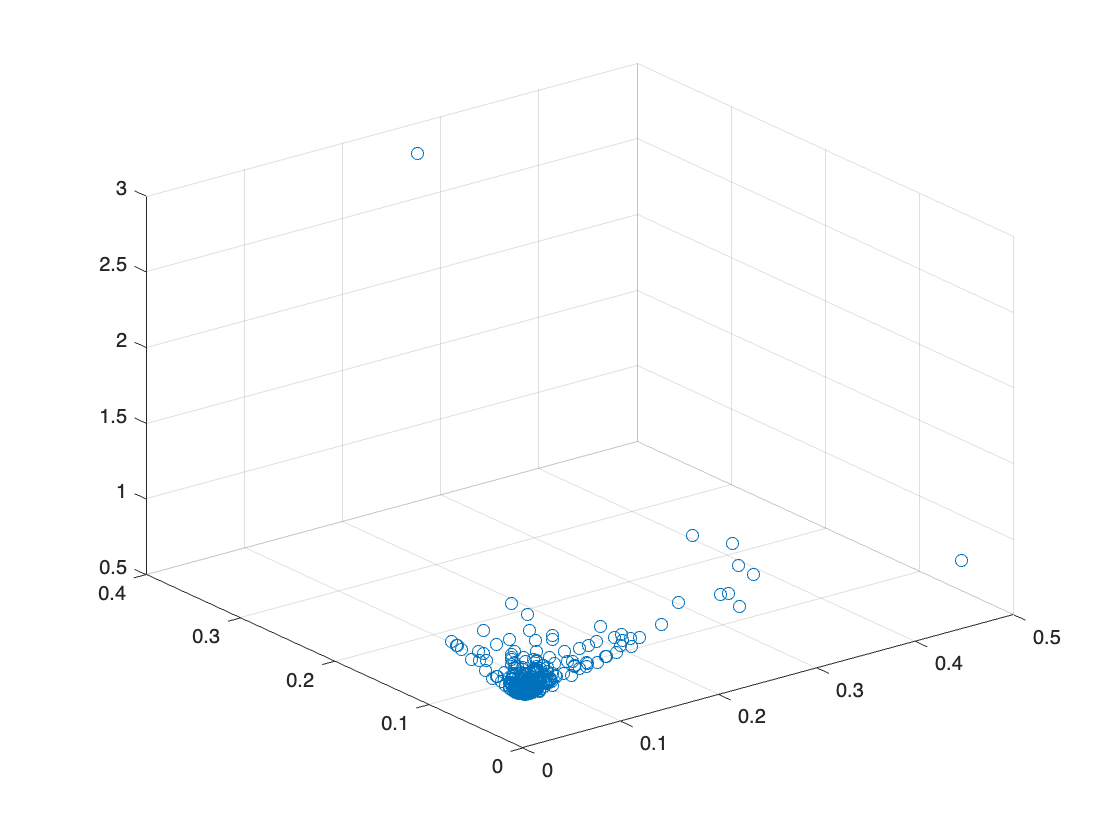

% Plot reconstruction
scatter3( xyzt(:,1) , xyzt(:,2) , xyzt(:,3) )